# Branch 1 basic config

%set roots
addpath(genpath('/Users/tony/Documents/Stanford/Chao_SEEG/'))
[server_root, comp_root, code_root] = AddPaths('Chao_iMAC');


%Initialize Directories
project_name = 'SEEG_test';

% Retrieve subject information
sbj_name = '2017_FT_SP_018_xiangxiang';
sbj_name = 'C18_49';

% center
if strcmp(sbj_name(6:7),'FT')
    center = 'fengtai';
else
    center = 'tiantan';
end

% Get block names
block_names = BlockBySubj(sbj_name,project_name)

% take care of the directory 
dirs = InitializeDirs(project_name, sbj_name, comp_root, server_root, code_root); 

% Get iEEG sampling rate and data format
[fs_iEEG, data_format] = GetFSdataFormat(center);

% Create subject folders and global_var
CreateFolders(sbj_name, project_name, block_names, center, dirs, 1);

% Copy the iEEG and behavioral files from server to local folders
parfor i = 1:length(block_names)
    CopyFilesServer(sbj_name,project_name,block_names{i},dirs) % CZ_important here
end

## Branch 2 - data conversion(rawdata extraction, naming, decimate etc.)

ref_chan = [];
epi_chan = [];
empty_chan = [];

if strcmp(data_format, 'edf')
    SaveDataNihonKohden_sortData(sbj_name, project_name, block_names, dirs, ref_chan, epi_chan, empty_chan) 
else
    error('Data format has to be edf ')
end

## Branch 3 - notch filtering & bipolar rereference

notch_and_BR(sbj_name, project_name, block_names, dirs)

## CCEP

## H2

## EI

%Step 1 
ER_pipeline_Chao(sbj_name, project_name, block_names, dirs , 'Band', 'EI') 

ER calculating: Block SZ1, Elec E1-E2
ER calculating: Block SZ1, Elec E2-E3
ER calculating: Block SZ1, Elec E3-E4


%Step 2

Nu = 0.8

Nu = 0.8000


Lamda = 500

Lamda = 500


Eta = 5

Eta = 5

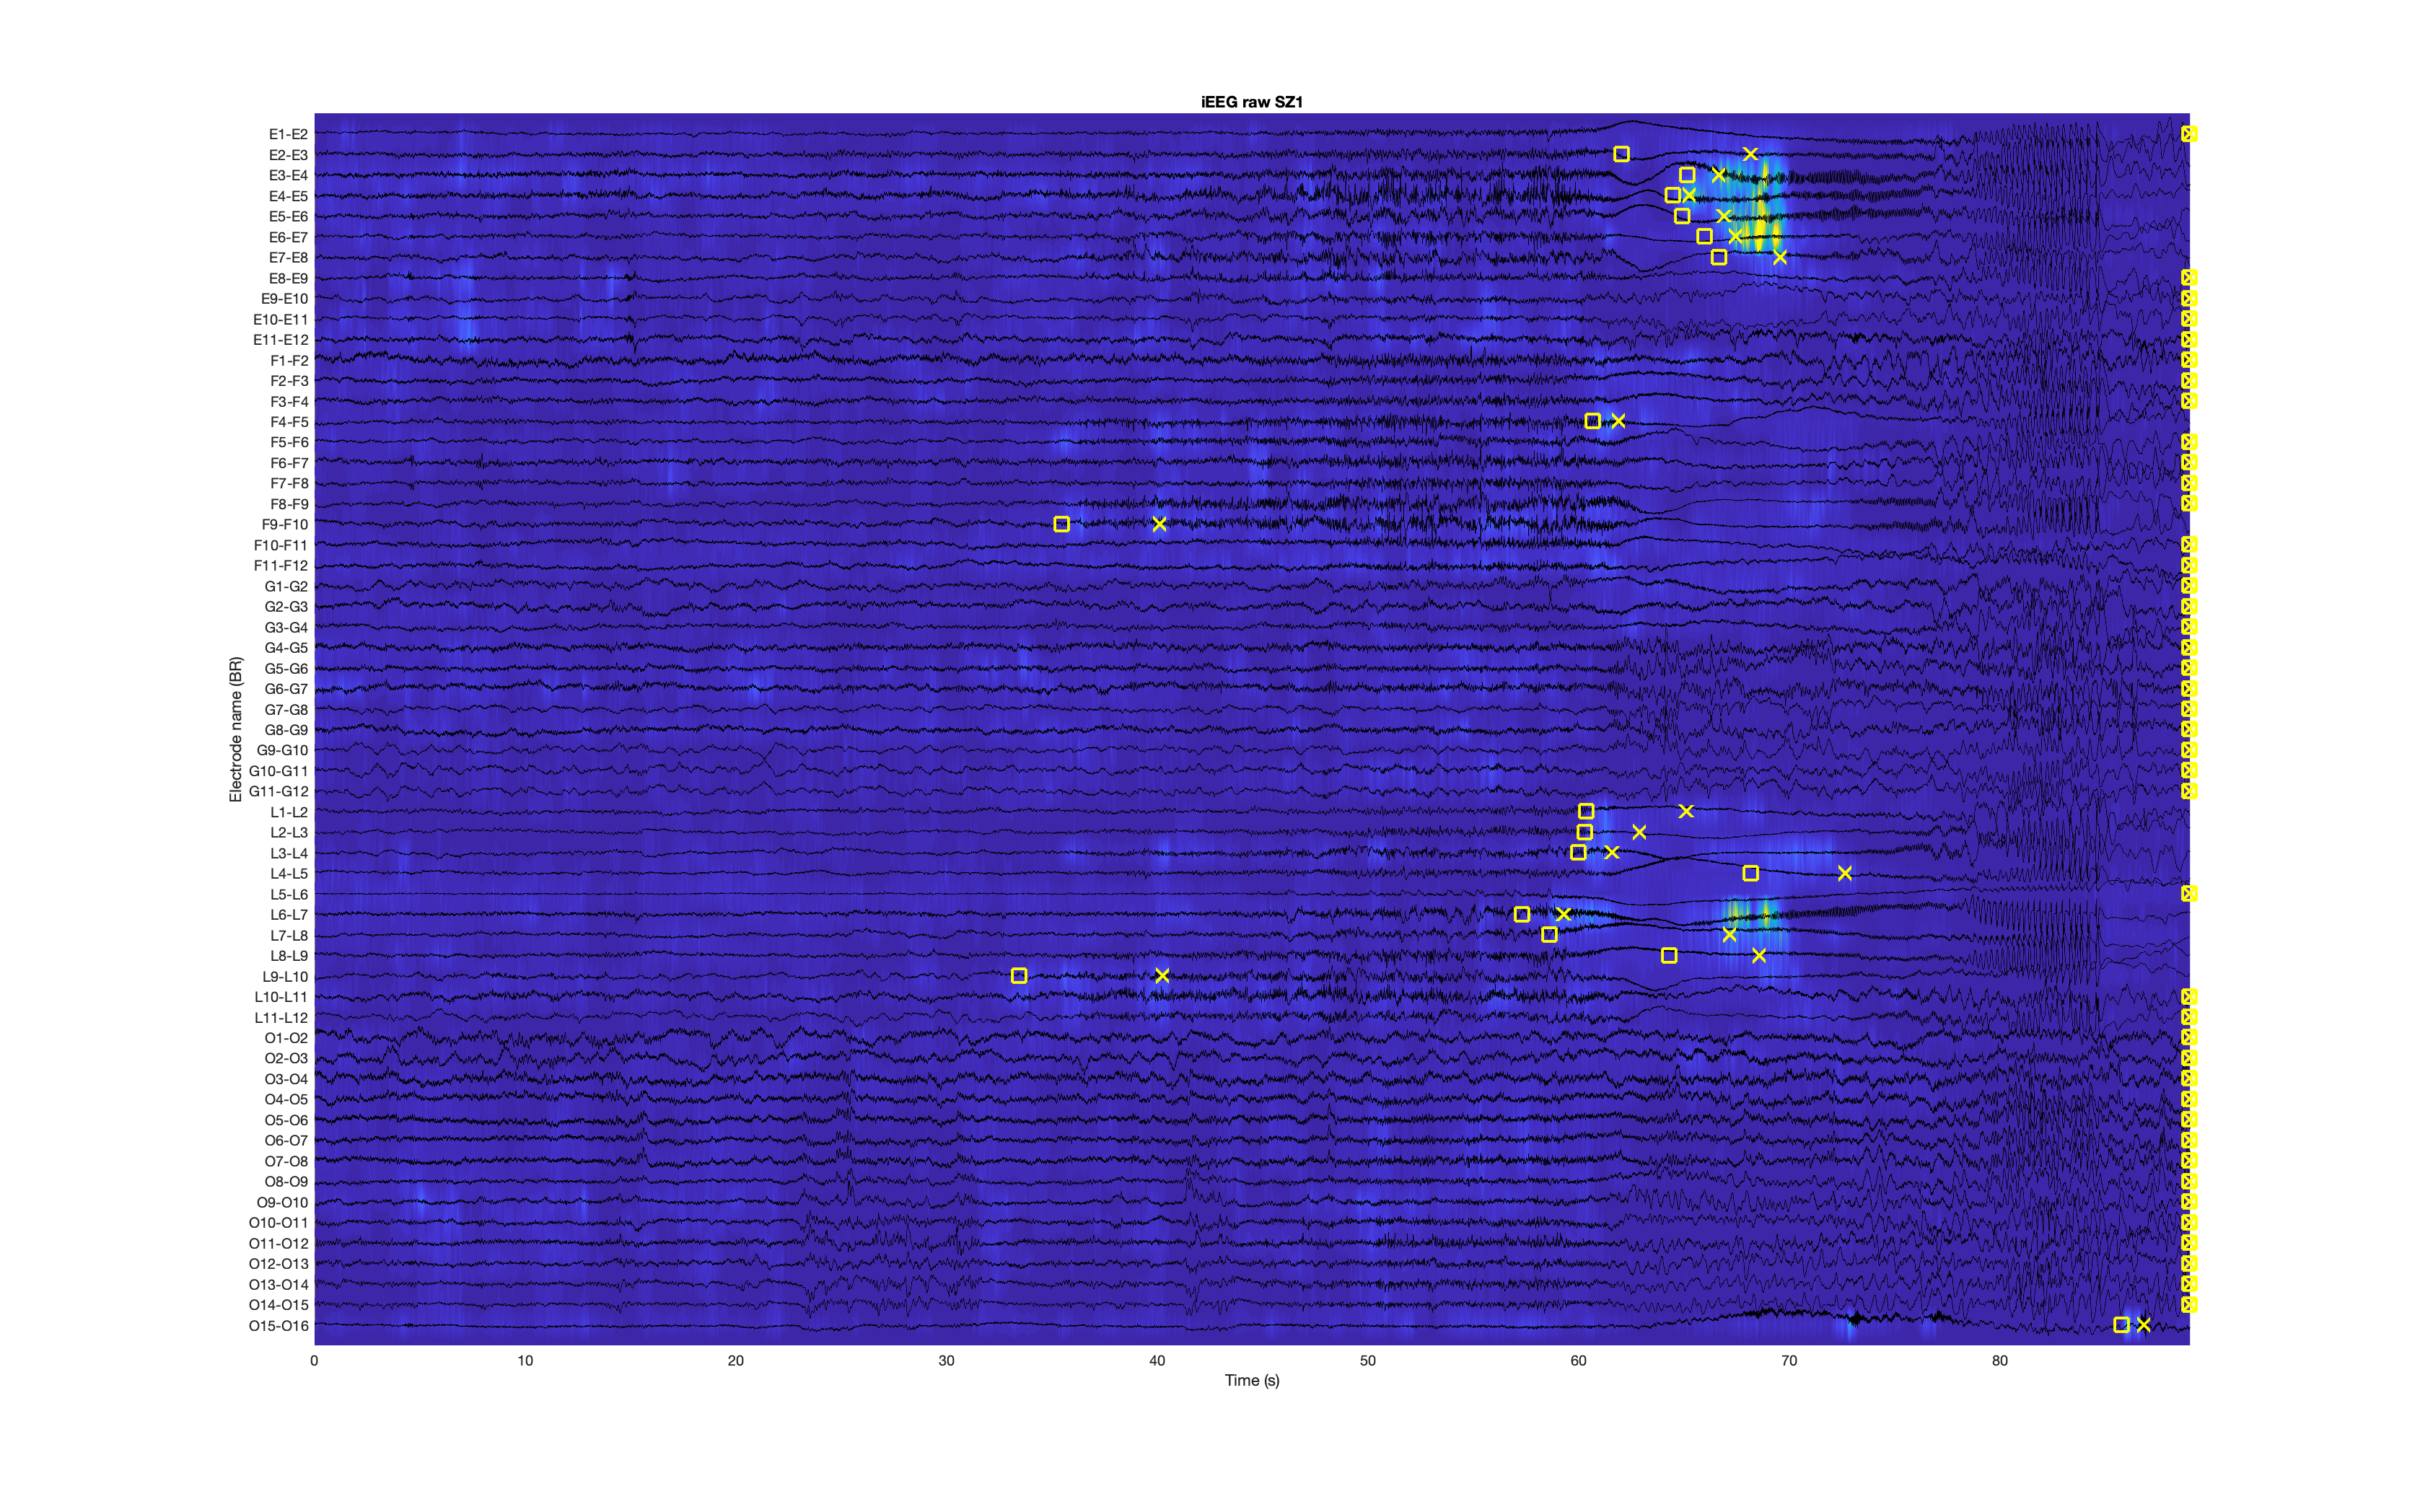

 

EI_pipeline_Chao(sbj_name, project_name, block_names, dirs, 'Band', 'EI',Nu,Lamda,Eta)

% ER

## localization